# ECE 580 Make-Up Project

Yen-Chun Chen

934559635

clear; 
close all; 
clc; 
format compact; 

#### 1. Plot the pole Q (Qp) of the dominant pole of a fourth-order Chebyshev filter as a function of αp.

N = 4;                          
Wp = 2*pi*20e3;                 % Cutoff frequency
alpha_p_values = 0.1:0.1:6;     % Passband ripple from 0.1 dB to 6 dB with each step 0.1

Qp_values = zeros(size(alpha_p_values)); % Initialize array for Qp values with different passband ripples

alpha_p_largest_when_Qp_less_than_5 = 0;
alpha_p_largest_when_Qp_less_than_3 = 0;
alpha_p_largest_when_Qp_less_than_1 = 0;

for i = 1:length(alpha_p_values)

    Rp = alpha_p_values(i);
    
    [z, p, k] = cheby1(N, Rp, Wp, 'low', 's');
    
    % Calculate the Q factor for each pole
    Q_values = abs(p) ./ (2 * abs(real(p)));
    
    % Find the dominant pole
    Qp_values(i) = max(Q_values);
    
    fprintf("%2d. alpha_p = %.2f dB when Qp = %.2f\n", i, Rp, Qp_values(i));

    % Find the largest alpha_p when Qp < 5
    if (Qp_values(i) < 5) && (Rp > alpha_p_largest_when_Qp_less_than_5)
        alpha_p_largest_when_Qp_less_than_5 = Rp;
    end

    if (Qp_values(i) < 3) && Rp > (alpha_p_largest_when_Qp_less_than_3)
        alpha_p_largest_when_Qp_less_than_3 = Rp;
    end

    if (Qp_values(i) < 1) && (Rp > alpha_p_largest_when_Qp_less_than_1)
        alpha_p_largest_when_Qp_less_than_1 = Rp;
    end

end

 1. alpha_p = 0.10 dB when Qp = 2.18
 2. alpha_p = 0.20 dB when Qp = 2.44
 3. alpha_p = 0.30 dB when Qp = 2.63
 4. alpha_p = 0.40 dB when Qp = 2.79
 5. alpha_p = 0.50 dB when Qp = 2.94
 6. alpha_p = 0.60 dB when Qp = 3.08
 7. alpha_p = 0.70 dB when Qp = 3.21
 8. alpha_p = 0.80 dB when Qp = 3.33
 9. alpha_p = 0.90 dB when Qp = 3.45
10. alpha_p = 1.00 dB when Qp = 3.56
11. alpha_p = 1.10 dB when Qp = 3.67
12. alpha_p = 1.20 dB when Qp = 3.78
13. alpha_p = 1.30 dB when Qp = 3.88
14. alpha_p = 1.40 dB when Qp = 3.99
15. alpha_p = 1.50 dB when Qp = 4.09
16. alpha_p = 1.60 dB when Qp = 4.19
17. alpha_p = 1.70 dB when Qp = 4.29
18. alpha_p = 1.80 dB when Qp = 4.40
19. alpha_p = 1.90 dB when Qp = 4.49
20. alpha_p = 2.00 dB when Qp = 4.59
21. alpha_p = 2.10 dB when Qp = 4.69
22. alpha_p = 2.20 dB when Qp = 4.79
23. alpha_p = 2.30 dB when Qp = 4.89
24. alpha_p = 2.40 dB when Qp = 4.99
25. alpha_p = 2.50 dB when Qp = 5.09
26. alpha_p = 2.60 dB when Qp = 5.18
27. alpha_p = 2.70 dB when Qp = 5.28
2

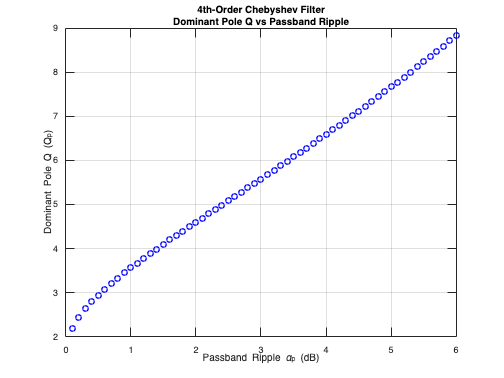

% Plot Qp as a function of alpha_p
figure;
plot(alpha_p_values, Qp_values, 'ob', 'LineWidth', 1.5);
xlabel('Passband Ripple \alpha_p (dB)');
ylabel('Dominant Pole Q (Q_p)');
title({'4th-Order Chebyshev Filter','Dominant Pole Q vs Passband Ripple'});
grid on;

#### 2. Find the value of the largest passband ripple αp if the condition Qp < 5 must hold. Repeat for Qp < 3, Qp < 1.

fprintf("When Qp < 5, largest passband ripple αp = %.2f\n", alpha_p_largest_when_Qp_less_than_5);

When Qp < 5, largest passband ripple αp = 2.40


fprintf("When Qp < 3, largest passband ripple αp = %.2f\n", alpha_p_largest_when_Qp_less_than_3);

When Qp < 3, largest passband ripple αp = 0.50


fprintf("When Qp < 1, largest passband ripple αp = %.2f\n", alpha_p_largest_when_Qp_less_than_1);

When Qp < 1, largest passband ripple αp = 0.00
